# **Task 1**

## **A)**



A=[2 3;4 -6];
b=[4;7];

% since AX=b => X=A^-1b

%A(2x2), b(2x1) multip is valid


if det(A)==0
    disp('invalid matrix equation');
else
X=inv(A)*b;
disp('X=');
disp(X);
end

X=


    1.8750
    0.0833



## B)

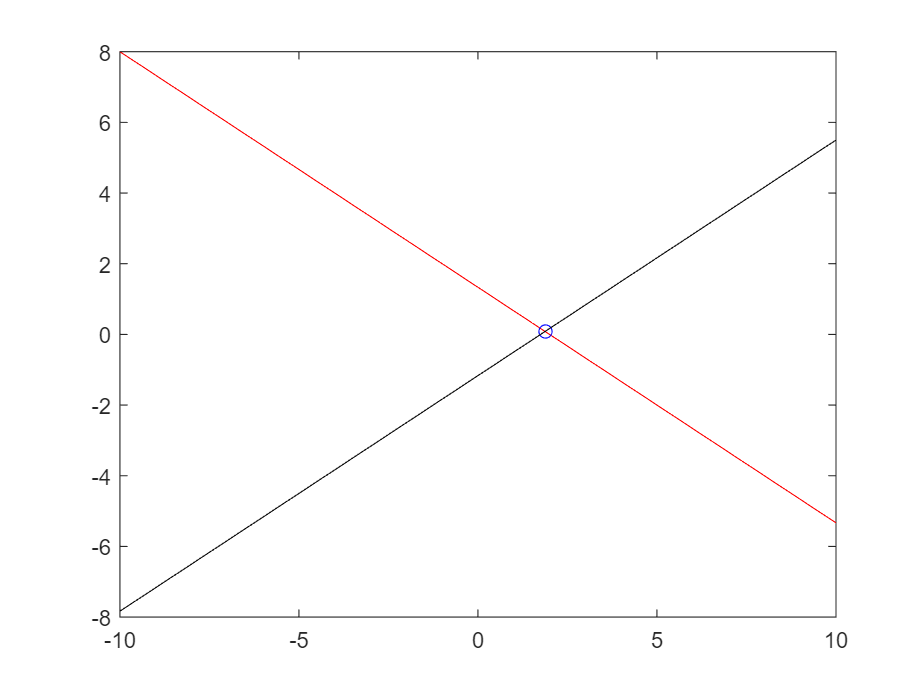

figure(1);
x=linspace(-10,10);
y1=(-2/3)*x+4/3;
plot(x,y1,'r');
hold on;
plot(X(1,1),X(2,1),'b--o');
y2=(4/6)*x-7/6;
plot(x,y2,'k');

## C)

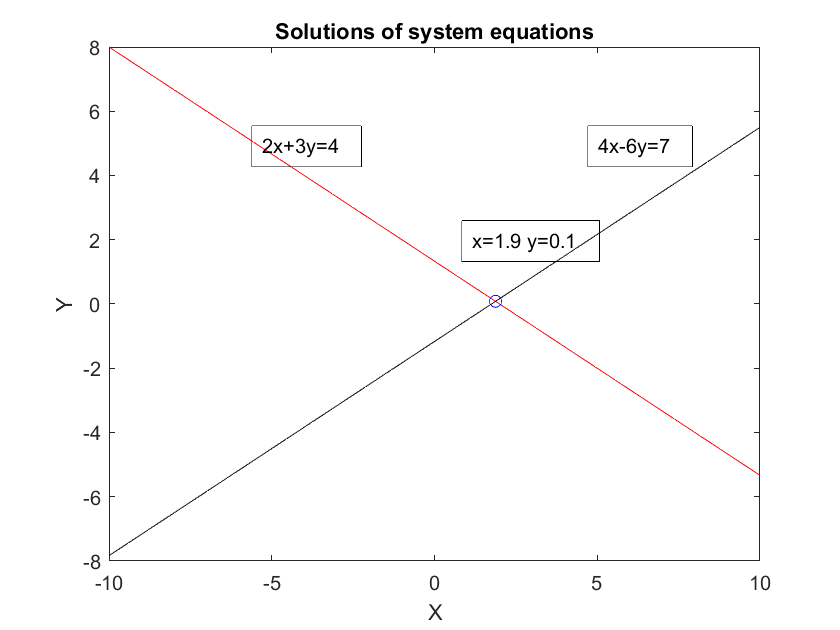

xlabel('X');
ylabel('Y');
title('Solutions of system equations');
dim1 = [.3 .5 .3 .3];
dim2 = [.7 .5 .3 .3];
dim3 = [.55 .35 .3 .3];
str1 = '2x+3y=4';
str2 = '4x-6y=7';
str3 = 'x=1.9 y=0.1';
annotation('textbox',dim1,'String',str1,'FitBoxToText','on');
annotation('textbox',dim2,'String',str2,'FitBoxToText','on');
annotation('textbox',dim3,'String',str3,'FitBoxToText','on');
hold off;
saveas(figure(1),'jedenc','png')

# **Task 2 **

## A)

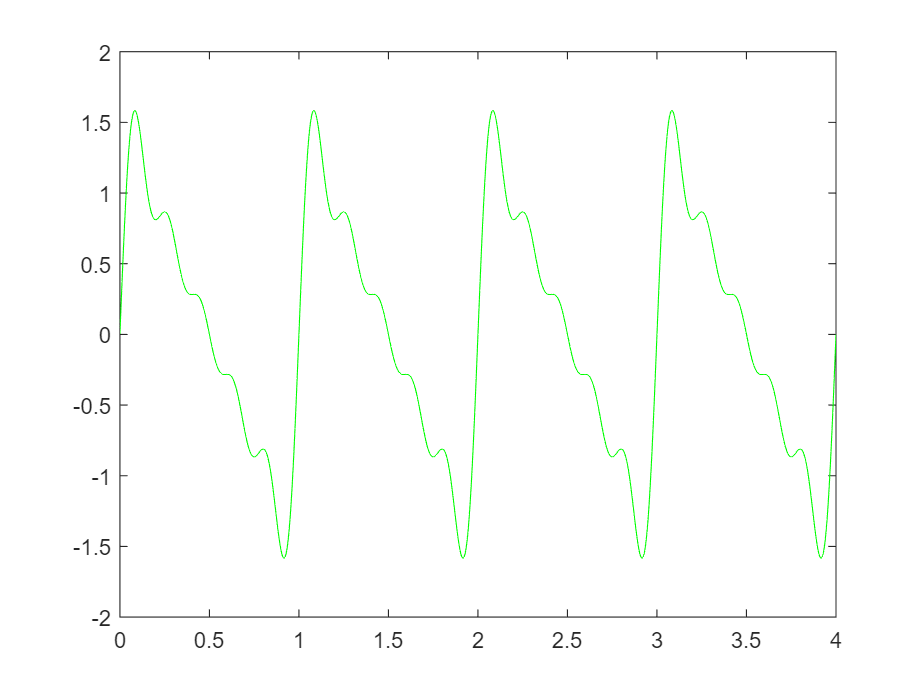



%i=[1:5]; %i(1x5)
y=0; %y(1x5)
t=[0:1/500:4];
for i=1:5
    y=y+(1/i)*sin(2*pi*i*t);
  
end
figure(2);
plot(t,y,'g'); %t(1x2001) , y(1x2001)
hold on;

## B)

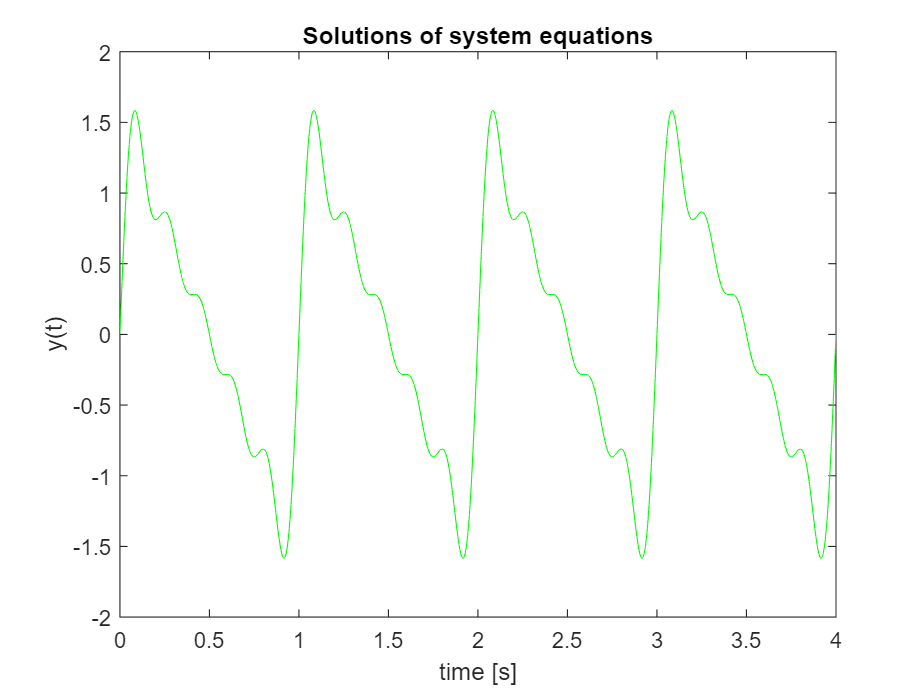

xlabel('time [s]');
ylabel('y(t)');
title('Solutions of system equations');

# **Task 3**

## A)

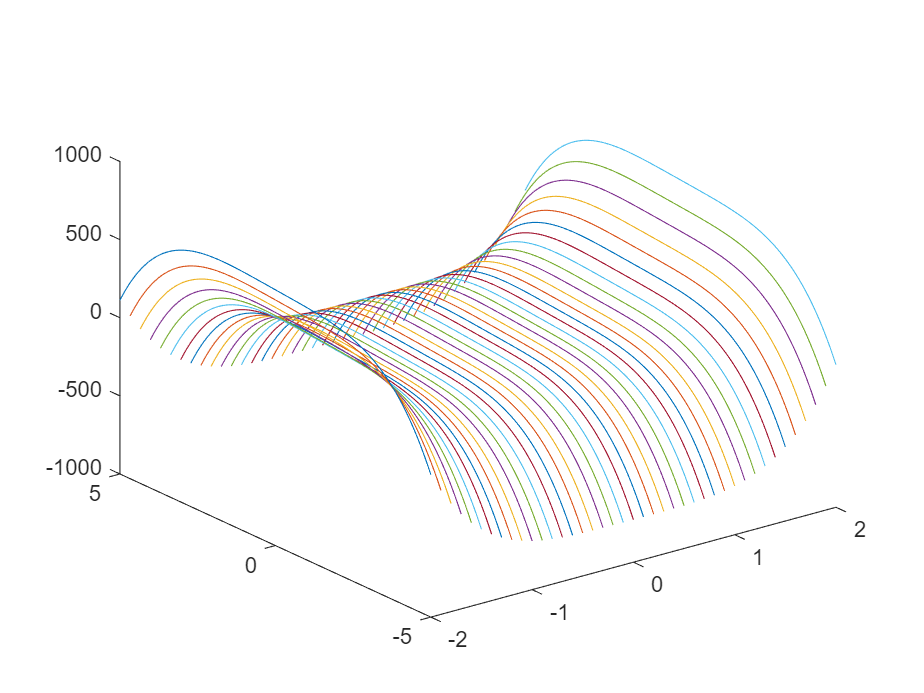



x=[-2:0.1:2]; %(1x41)

y=[-5:0.1:5]; %(1x101)

[x,y]=meshgrid(x,y); %both (101x41)

z=40*x.^4+x-x-y.^4+20*y-3; %(101x41)
figure(3);
plot3(x,y,z);

## B)

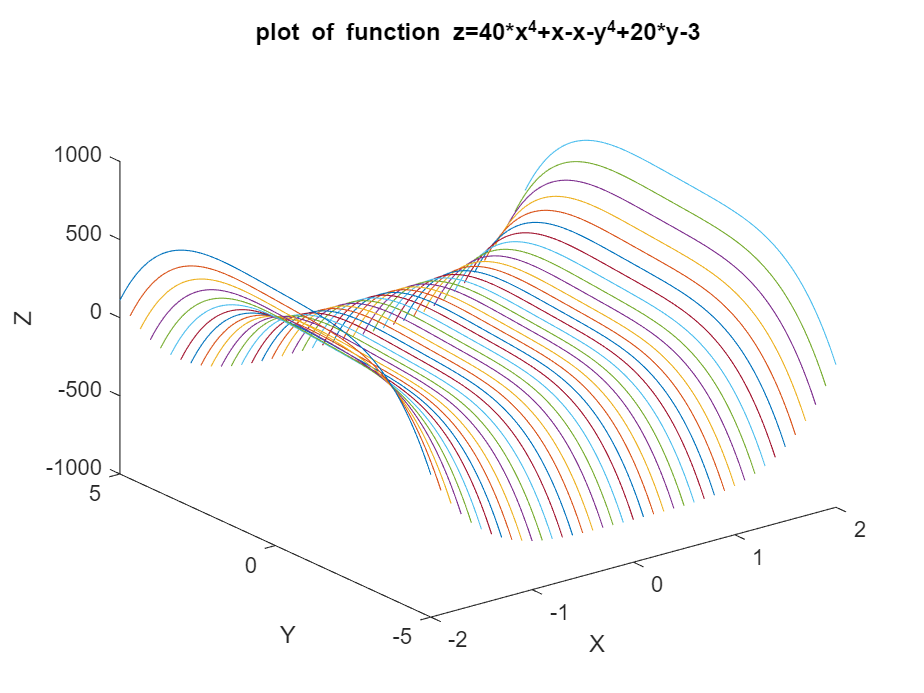


xlabel('X');
ylabel('Y');
zlabel('Z');
title('plot of function z=40*x^4+x-x-y^4+20*y-3');

## C)

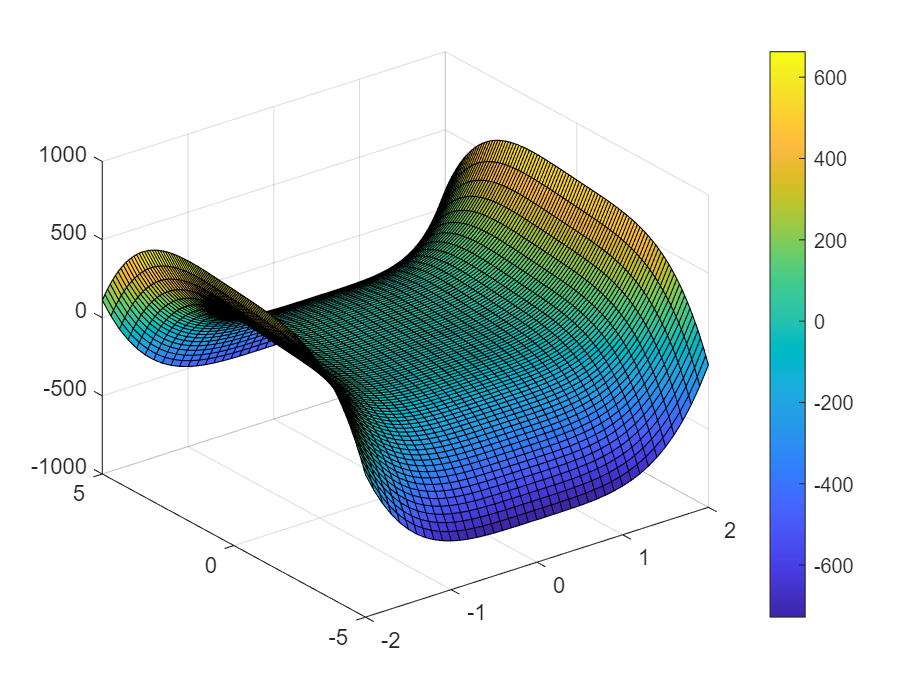

figure(4);
surf(x,y,z);
colorbar;

# **Task 4**

## A)

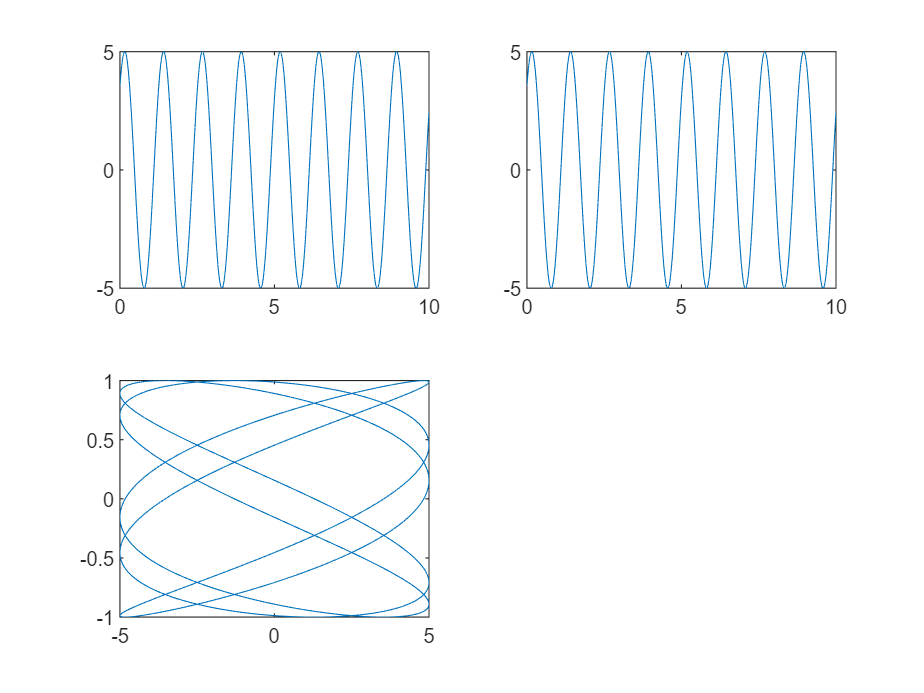

t=out.bout.Time;
x=out.bout.Data(:,1);
y=out.bout.Data(:,2);

figure(5);
subplot(2,2,1);
plot(t,x);

subplot(2,2,2);
plot(t,x);
subplot(2,2,3);
plot(x,y);

## B)

#### For A=B=5 we have the following curve:

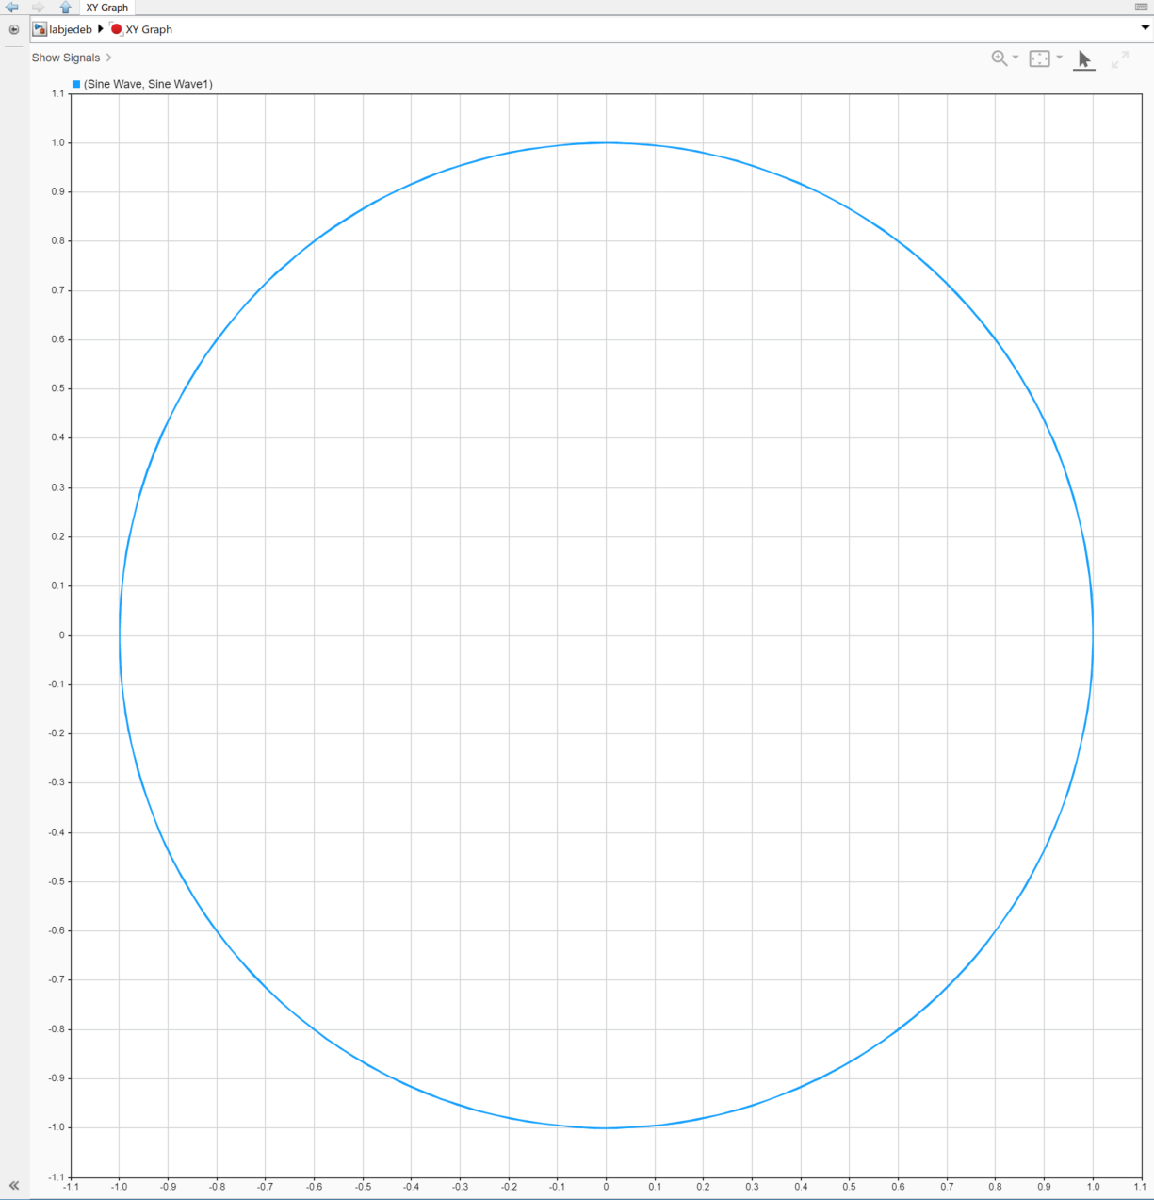

For A/B=0.5:

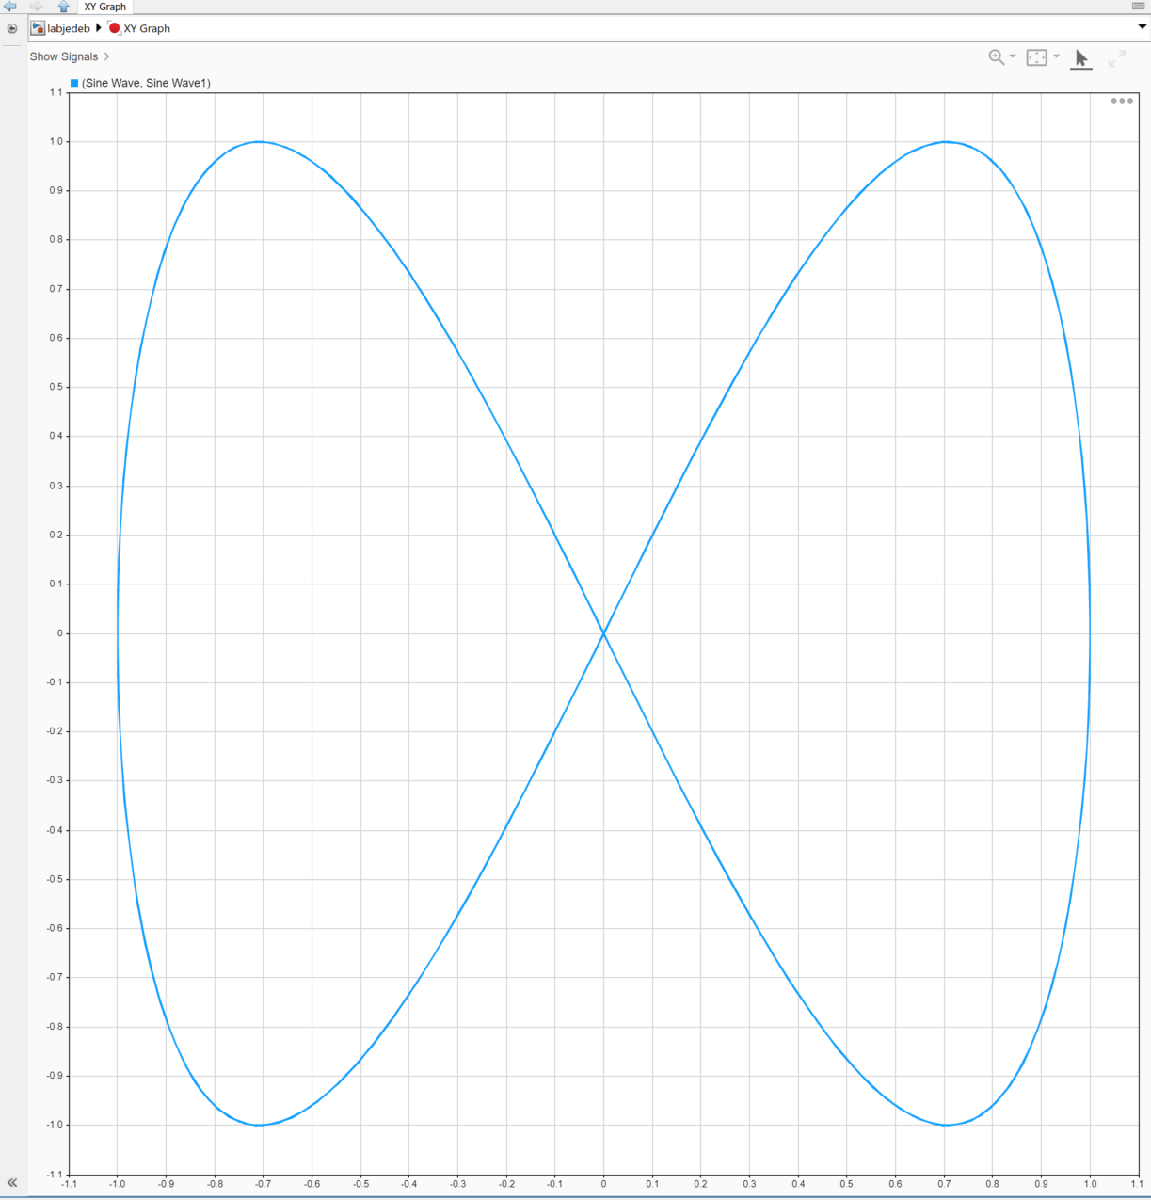

For A/B=0.33:

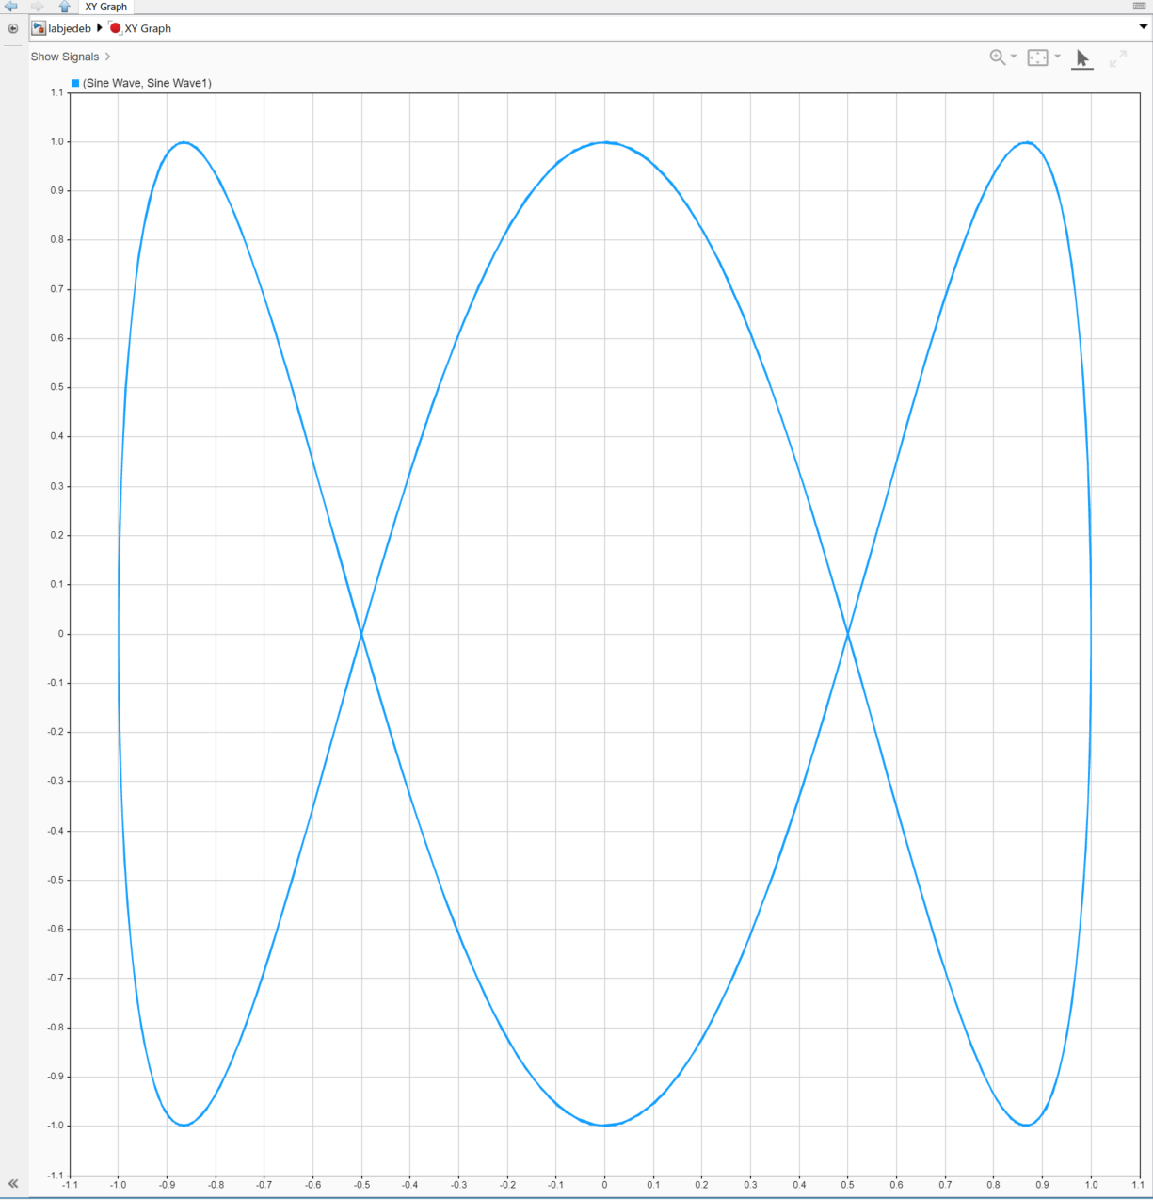

#### The ratio of A to B influences the number of knots formed by the curves. Where for A=B we heve 0 knots, perfect circle, B being two times greater than A we have one horisontal knot and for B three times greater than A we have two knots. Since B is our y input the knots are horisontal. Af A was proportionally bigger than B the knots would be vertical (plot rotated by 90 degrees)

## C)

## for pi

#### 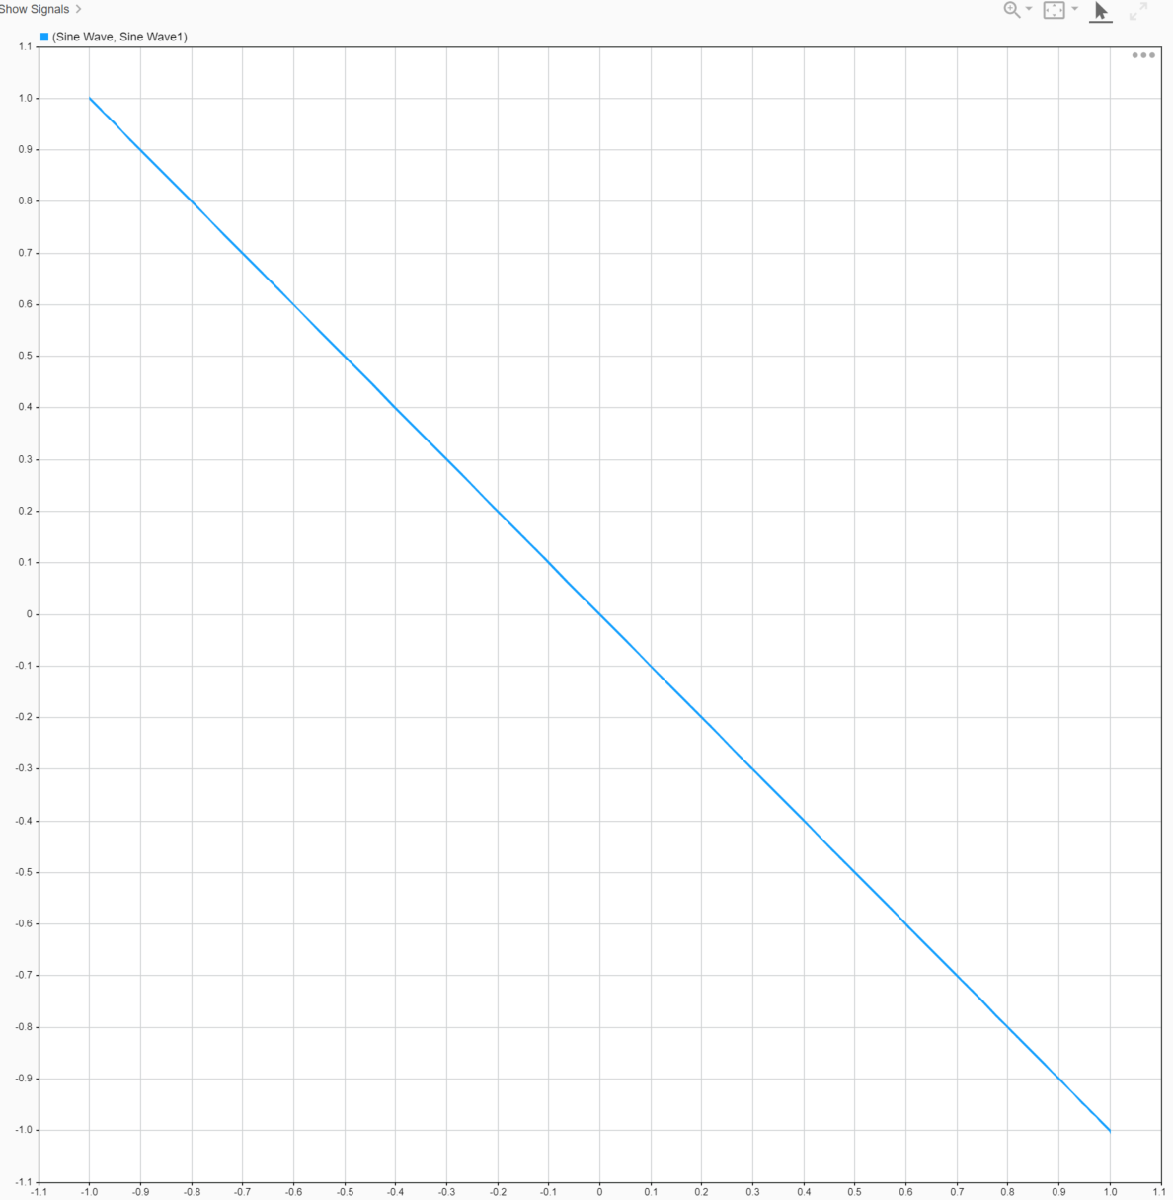 

## For p/4

## 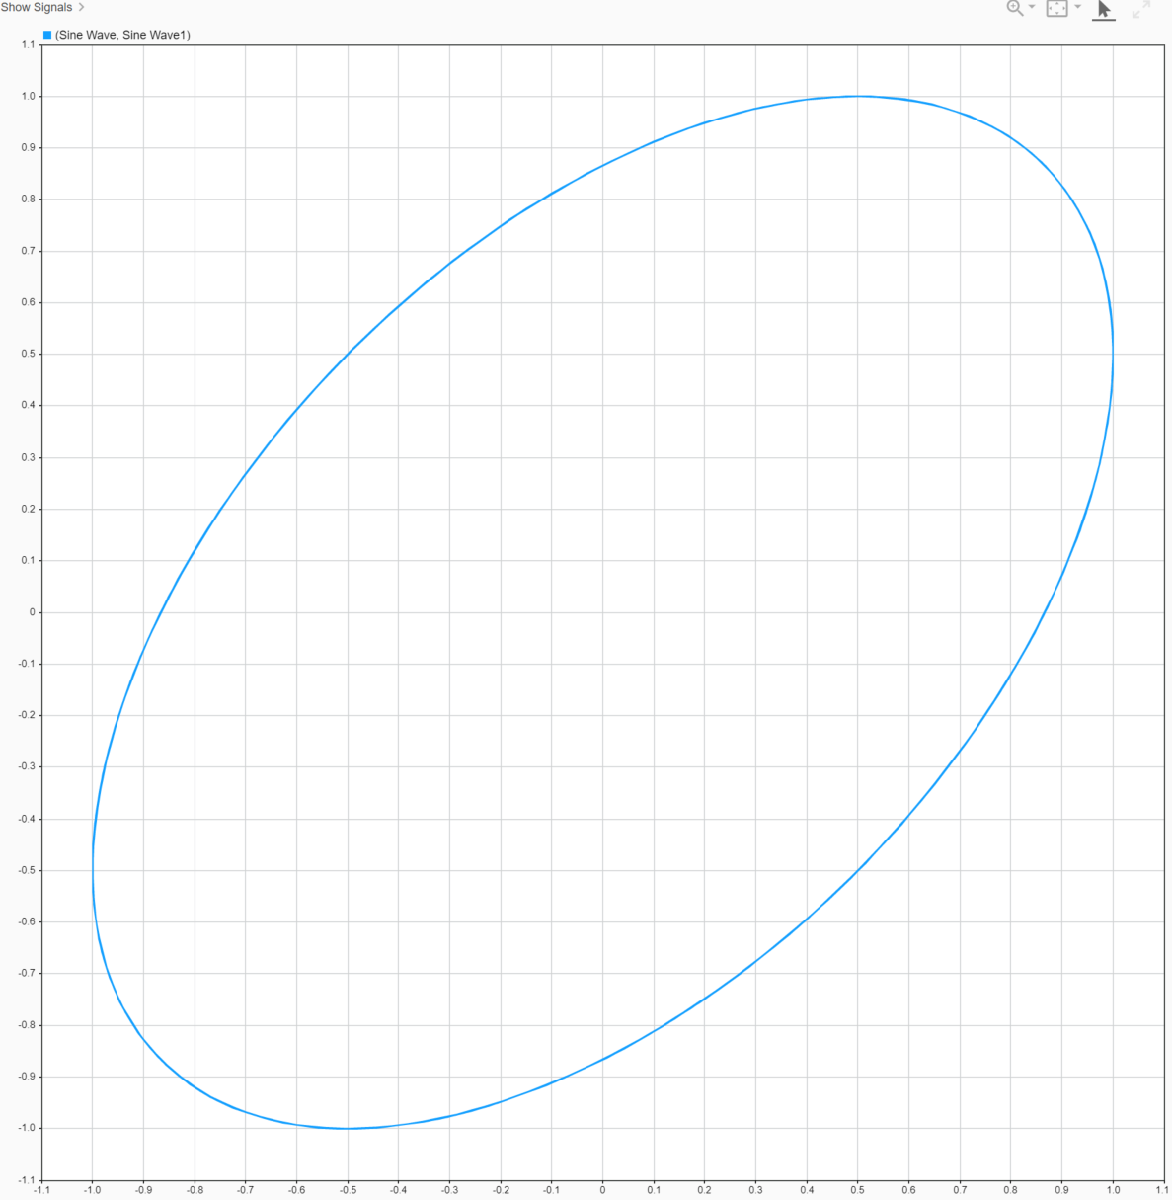

## For pi/6

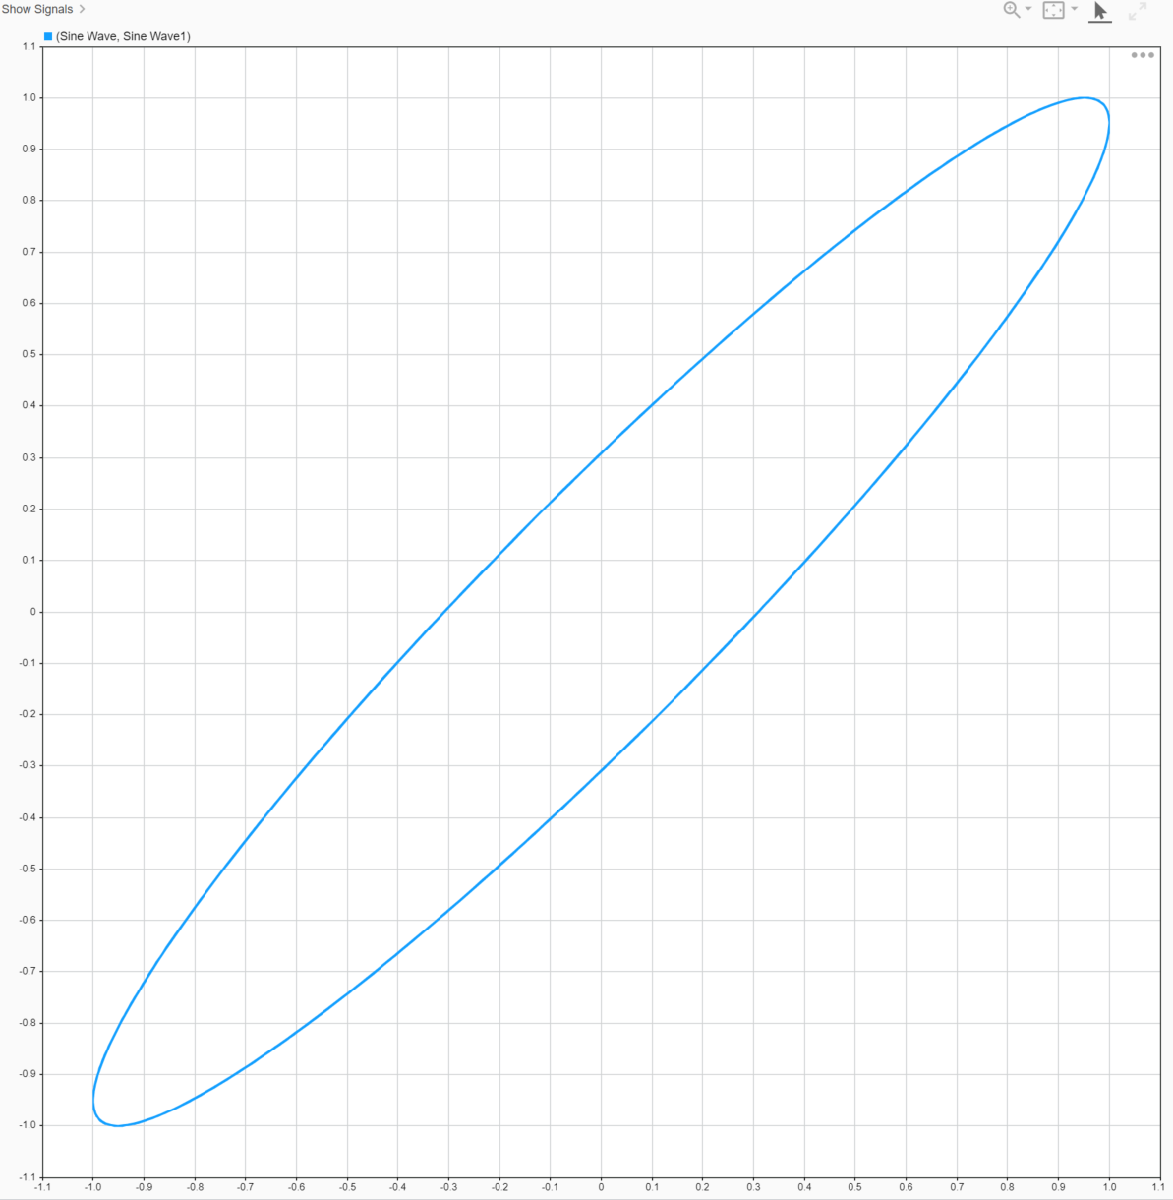

## The phase shift distorts the circle. For shift equal to pi we can observe a strait line y=-x since the values of one functions are inverted. If phase eqals 0 than we would observe a y=x line since all values would correspond to each other. For pi/4 and pi/6 we can observe an increace in the deformation of the circle. In conclusion for phase increace from 0 to pi/2 the plot goes from a line (x=y) to a circle and from pi/2 to pi the circle changes gradually into a line (y=-x).